% Presetting
PosExtract=[0; 0; 0; 1];

% 3-DoF Manipulator Type 2 Forward Kinematics
syms L1 L2 L3 L4 theta1 theta2 theta3 theta4;

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = L1;
T01 = DHParameter(a0, alpha0, d1, theta1)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm1 to Arm2
a1 = 0;
alpha1 = sym(pi)/2;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2)

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{2}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
T34 = DHParameter(a3, alpha3, d4, theta4)

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & L_{3}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Arm3 to Endpoint
a4 = L4;
alpha4 = 0;
d5 = 0;
theta5 = 0;
T4E = DHParameter(a4, alpha4, d5, theta5)

$$T4E = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{4}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Base to Endpoint
T0E = simplify(T01*T12*T23*T34*T4E)

$$T0E = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1}\right) & -\sigma_{1}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{1}\right) & -\sigma_{1}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3} & 0 & L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)+L_{4}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)+L_{4}\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$


% Position of Endpoint according to Base Coordinate
p0E=T0E*PosExtract

$$p0E = \left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)+L_{4}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\right)\\ \sin\left(\theta_{1}\right)\,\left(L_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\cos\left(\theta_{2}\right)+L_{4}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\right)\\ L_{1}+L_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{2}\,\sin\left(\theta_{2}\right)+L_{4}\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ 1 \end{array}\right)$$

% 3-DoF Manipulator Type 2 Kinematics test by plot graph
theta1=pi/6;
theta2=pi/6;
theta3=pi/6;
theta4=pi/6;
L1=200;
L2=200;
L3=200;
L4=200;

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = L1;
T01 = DHParameter(a0, alpha0, d1, theta1);

T01 =     0.8660   -0.5000         0         0
    0.5000    0.8660         0         0
         0         0    1.0000  200.0000
         0         0         0    1.0000



% Arm1 to Arm2
a1 = 0;
alpha1 = pi/2;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

T12 =     0.8660   -0.5000         0         0
    0.0000    0.0000   -1.0000         0
    0.5000    0.8660    0.0000         0
         0         0         0    1.0000



% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3);

T23 =     0.8660   -0.5000         0  200.0000
    0.5000    0.8660         0         0
         0         0    1.0000         0
         0         0         0    1.0000



% Arm3 to Endpoint
a3 = L3;
alpha3 = 0;
d4 = 0;
T34 = DHParameter(a3, alpha3, d4, theta4);

T34 =     0.8660   -0.5000         0  200.0000
    0.5000    0.8660         0         0
         0         0    1.0000         0
         0         0         0    1.0000



% Arm3 to Endpoint
a4 = L4;
alpha4 = 0;
d5 = 0;
theta5 = 0;
T4E = DHParameter(a4, alpha4, d5, theta5);

T4E =      1     0     0   200
     0     1     0     0
     0     0     1     0
     0     0     0     1


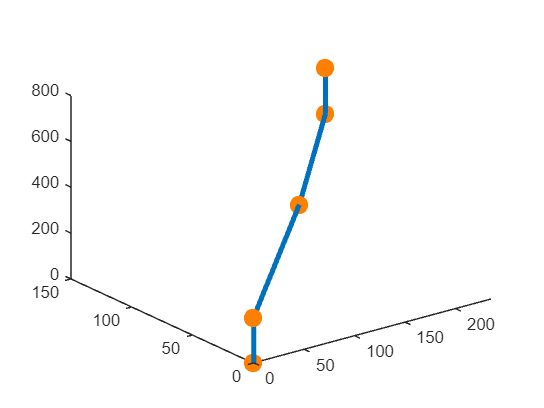


% Base to Each Coordinate
T02 = T01*T12;
T03 = T01*T12*T23;
T04 = T01*T12*T23*T34;
T0E = T01*T12*T23*T34*T4E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p03=T03*PosExtract;
p04=T04*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot3([PosExtract(1,1), p02(1,1), p03(1,1), p04(1,1), p0E(1,1)], [PosExtract(2,1), p02(2,1), p03(2,1), p04(2,1), p0E(2,1)], [PosExtract(3,1), p02(3,1), p03(3,1), p04(3,1), p0E(3,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0];